First-order function

function [tt, yy] = plot_firstorder(tau, f, label)
    tt = linspace(0, 4*tau);
    yy = f*(1-exp(-tt/tau));
    plot(tt,yy, 'DisplayName',label);
end

plot

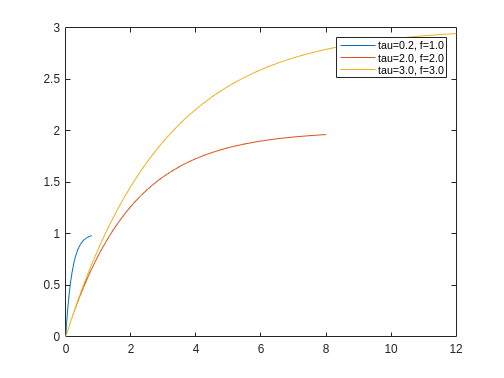

figure(1);
clf()
taus = [0.2, 2, 3];
fs =  [1, 2, 3];
for ii = 1:length(fs)
    ll = sprintf("tau=%.1f, f=%.1f",taus(ii),fs(ii));
    plot_firstorder(taus(ii),fs(ii),ll);
    hold on
end
legend()